% Code to plot a "continous" signal, sample, downsample, upsample and 
% interpolate (with ideal lowpass filter)
% Taisa Kushner
% Signals and Systems II
% plot a signal and spectrum for HW 5

%% HOW TO RUN A SECTION OF CODE %%
% Sections are separated with '%%' (such as this section is here)
% To "run" a section at a time, click your mouse in the section
% you want to run. This should highlight the code within
% the section, while the code outside of the section remains 
% not highlighted (it is yellow on my computer, but may be different
% depening on your Matlab settings). Then click the "Run Section" button at the top of Matlab
%% 


##  "Base Information" Run this first before any other section



clear all
close all

% CHANGE THIS PARAMETER fs %
fs = 14400;       % sampling frequency (Change this to match what you found)
ts = 1/fs;      % sampling interval
a = 144;
b = 36;
c = 4;
% CHANGE THIS PARAMETER fo %
A  = sym([a/2, b/2, c/2]);
fo = sym2poly(gcd(A))       % fundamental freq in hz (Change this to match what you found)

fo = 2

fmax = a/2;
N  = fs/fo      % number of samples

N = 7200

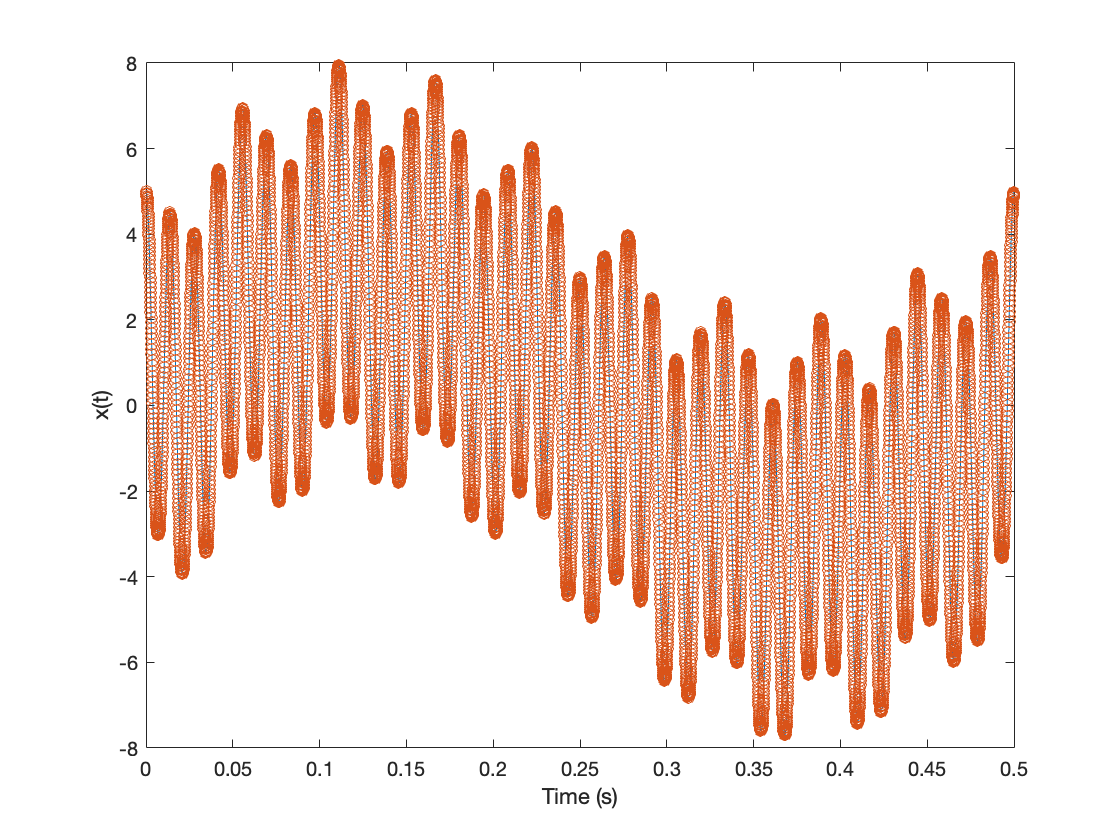

to = 1/fo;      % fundamental interval 
n  = 0:N-1;     % the labels of our sequence
nts= n*ts;      % the labels of our sampled points in time

M  = 4096;      % this can be anything, but 4096 is the usual number of adc spots
t  = linspace(0,to,M); %sample locations


% CHANGE THIS FUNCTION x%
% x = 2*sin(40*pi*t); Changed from to below function. 
x  = 4*cos(a*pi*t)+cos(b*pi*t)+3*sin(c*pi*t); %the "continuous" plot (Change this to match the signal in your homework)

figure(1)
plot(t,x)       % plot the "continuous" signal
xlabel('Time (s)') 
ylabel('x(t)')

% CHANGE THIS FUNCTION xs%
% Here the times n*ts are your sampled location points, eg your "time" vector
xs  = 4*cos(a*pi*n*ts)+cos(b*pi*n*ts)+3*sin(c*pi*n*ts); %the function defined only at your samped points (again, change this to match the signal in your homework)

hold on
plot(n*ts, xs, 'o') % plot dots at your sampled locations
 hold off


display(strcat('The number of samples is : ', string(N)))

    "The number of samples is :7200"



## Take the discrete time fourier transform of your sampled data

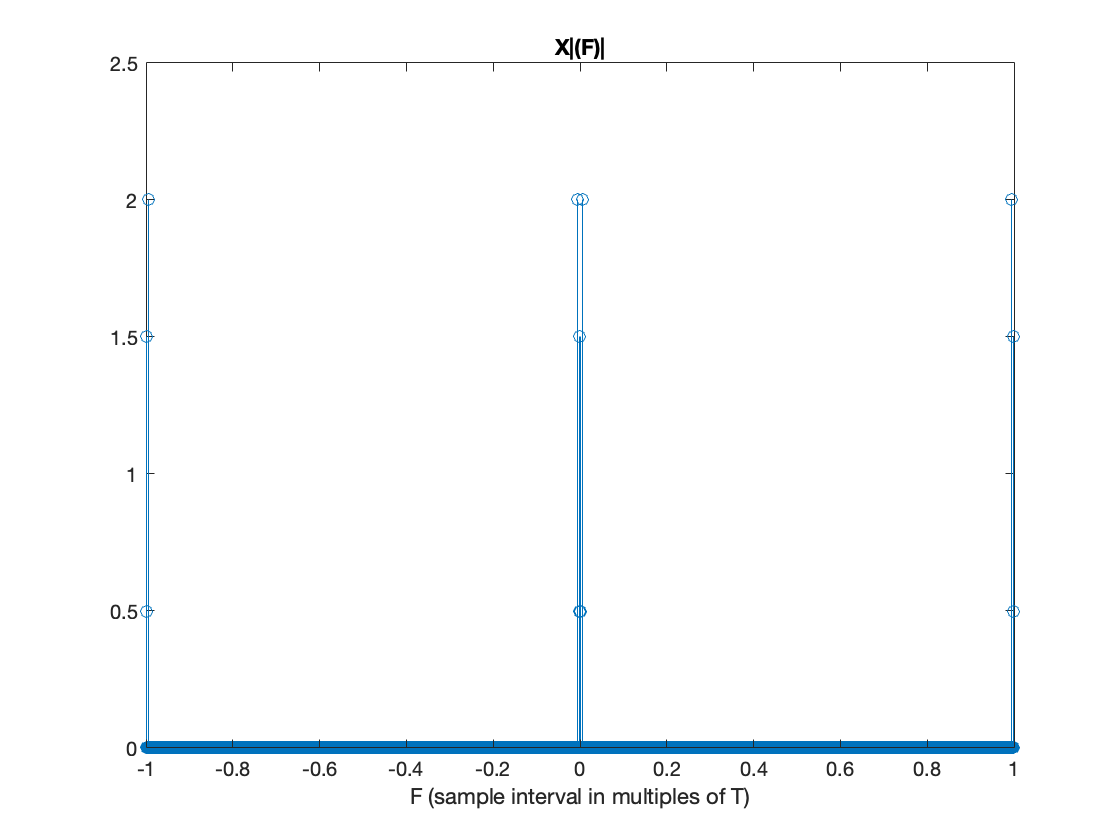


X = fft(xs); %this function takes the fast fourier transform of your sampled data
X = abs(X)/N; %need to divide by the number of samples
X = [fliplr(X(2:end)) X]; % replicate the negative frequencies 
F = -1:1/N:1; %this is just giving us location to plot at

figure(2)
stem(F(2:end-1),X) %stem plots vertical lines (rather than connecting points across the x-axis like plot() does)
title('X|(F)|')
xlabel('F (sample interval in multiples of T)')

## Change the labels on your Fourier Transform plot from the prior section

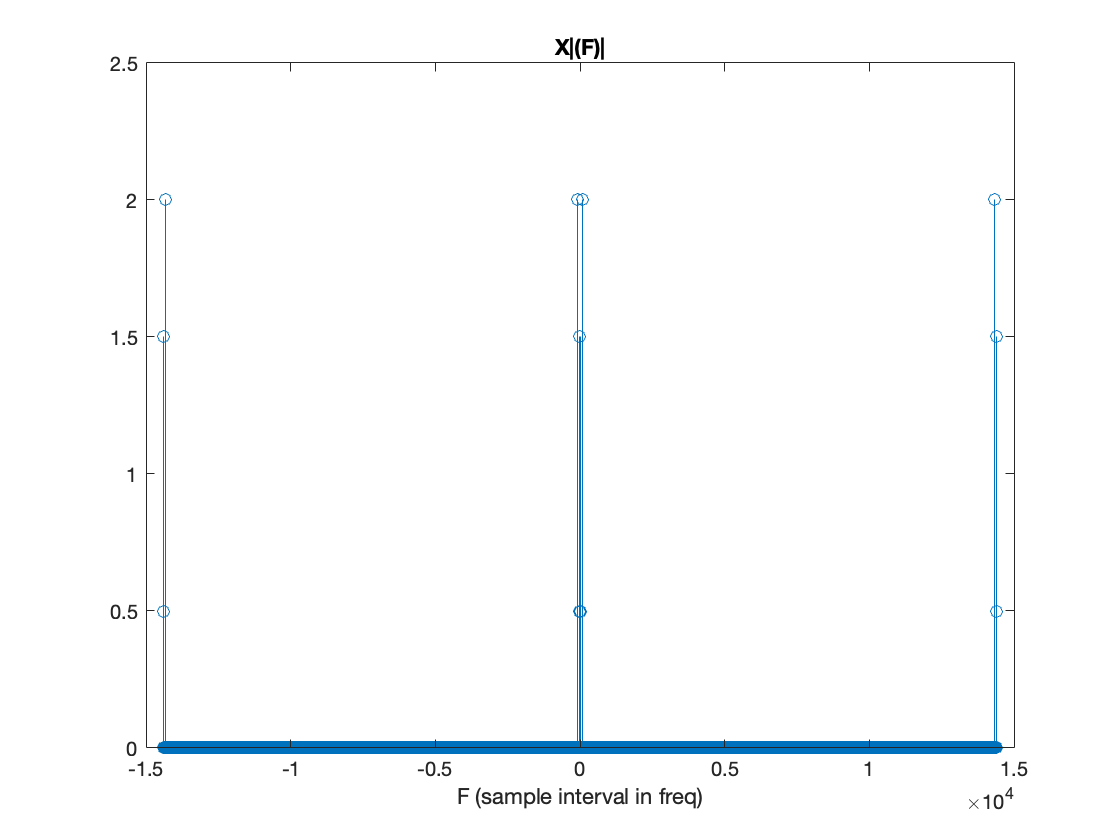


% change the labels on the x-axis from multiples of the time interval to time in seconds by diving by the time interval 
figure(4)
stem(F(2:end-1)/ts,X) % we divide by the time interval so the x-axis is in frequency (hz)
title('X|(F)|')
xlabel('F (sample interval in freq)')

## Fourier transform of the "continuous" signal

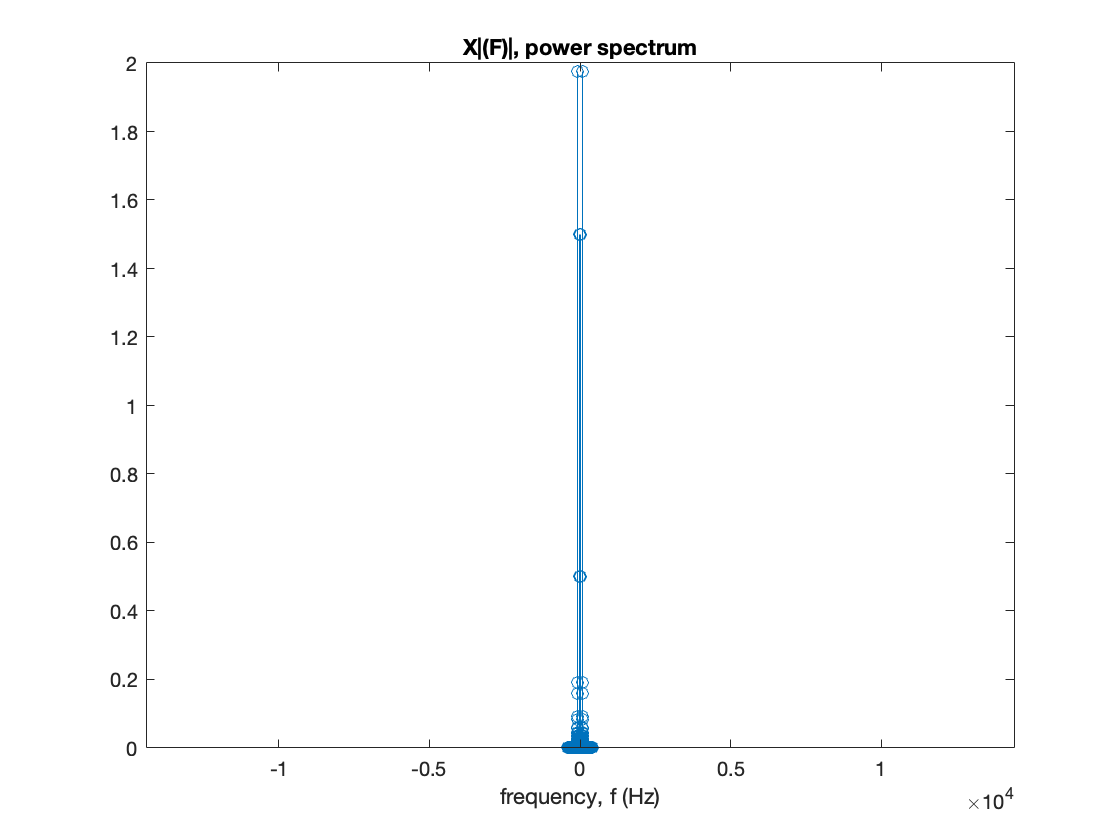


% Note: this is not truly "continuous" but just very high rate of sampling
% a discrete signal
Tmax = 10*to; %high rate to sample at
tt = linspace(0,Tmax,M);
xtt = 4*cos(a*pi*tt)+cos(b*pi*tt)+3*sin(c*pi*tt);
X = fftshift(fft(xtt)); %fftshift shifts the zero freq component to the center of the plot
X = abs(X)/M;
f = (-M/2:(M/2)-1)/Tmax;
figure(3)
stem(f,X)
xlim([-fs, fs])
title('X|(F)|, power spectrum')
xlabel('frequency, f (Hz)')

## Downsample by a factor of SS


%set up vector nans
%change d to any number less than 2 for problem 7. 
d = 2;
SS = fs/(d*fmax) %Change this to be your downsampling rate (whole number)

SS = 100

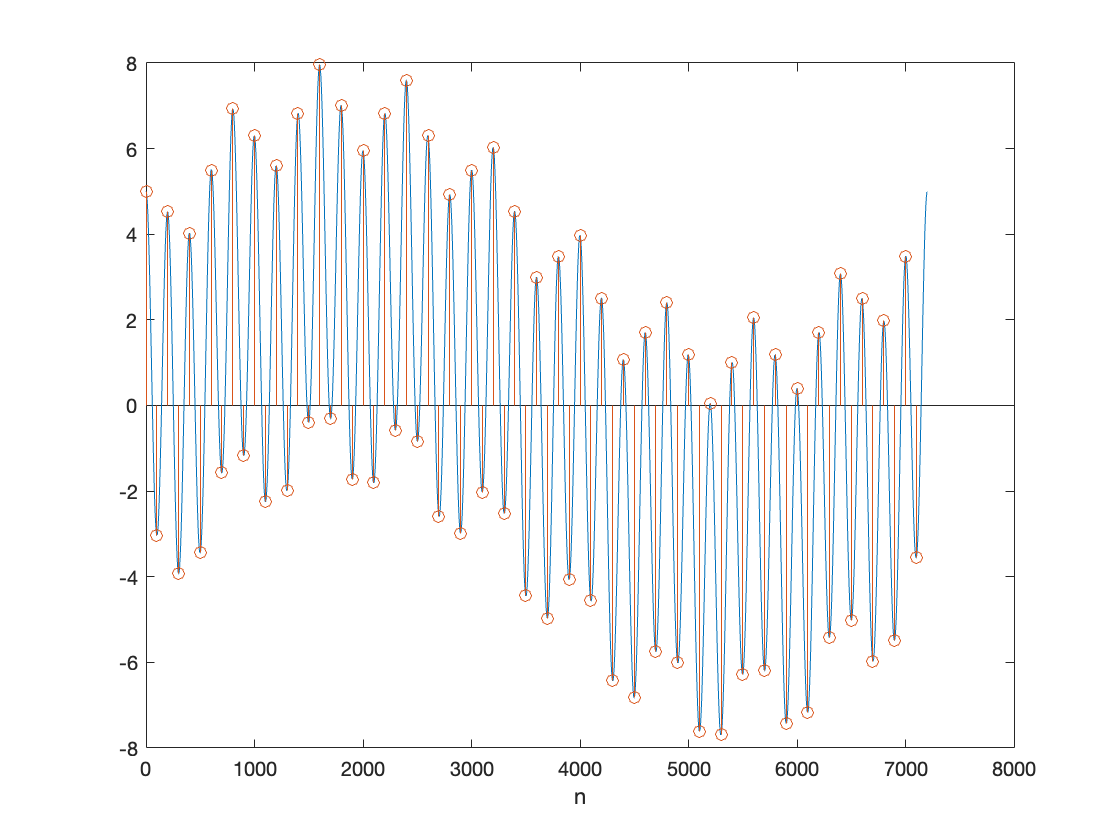



 

%SS = fs/(d*fmax)
Nd = N/SS; % this is our new number of data points
xd = nan(1,N); %create an empty arry of non a number (nan) terms
xd(1:SS:end) = xs(1:SS:end); %pick every SSth value from your original data, and keep it (ignmore the others)

figure(7)
plot(n,xs)
hold on
stem(n, xd) %now we plot the data we have kept
hold off
xlabel('n')


%drop the terms that are "zero" (in our case it is nan, as it is easier to keep
%track of)
xd(isnan(xd))=[];
%check the length of xd, is it as expected?
display(strcat('length of xd is: ', string(length(xd))))

    "length of xd is:72"



## Upsample by a factor of UU


UU = 2*SS; % Change this value to be your upsampling rate
Nup = Nd*UU

Nup = 14400

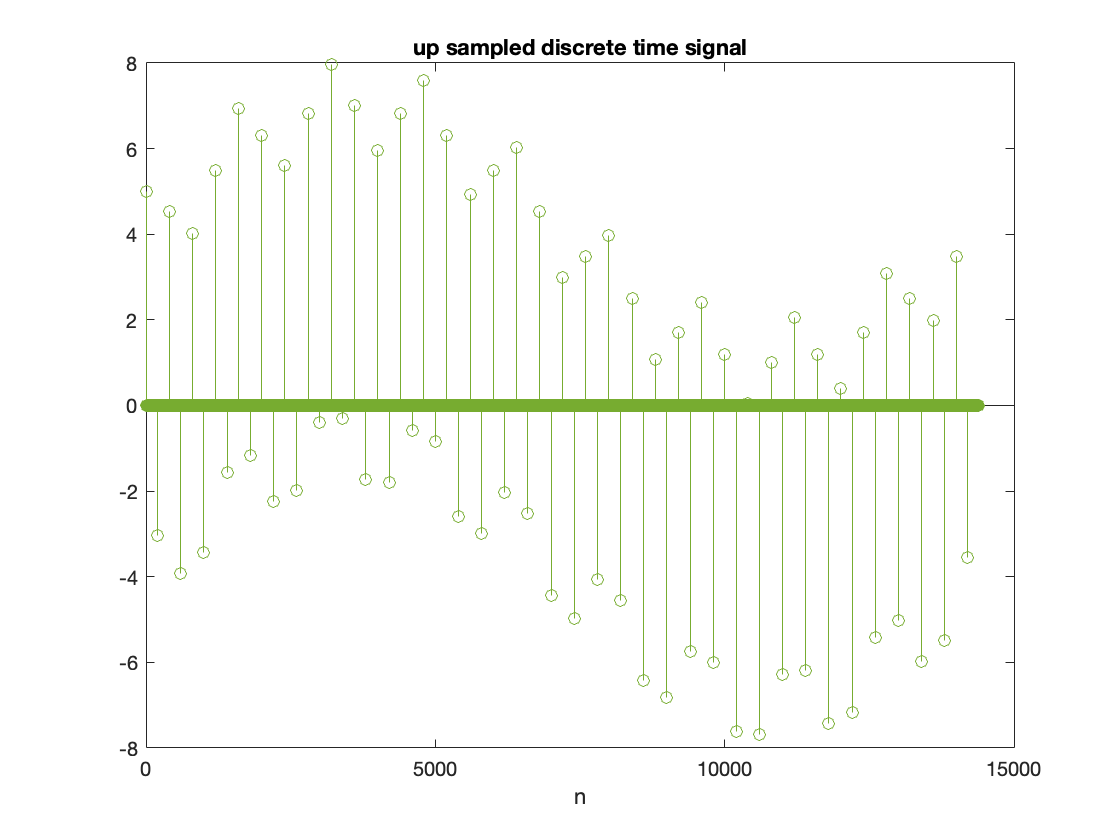

xup = zeros(1,Nup);
xup(1:UU:end) = xd;
figure(11)

plot(Nup,xs)
hold on
stem(xup)
hold off
xlabel('n');
title('up sampled discrete time signal')

## Interpolate the down sampled then up sampled data

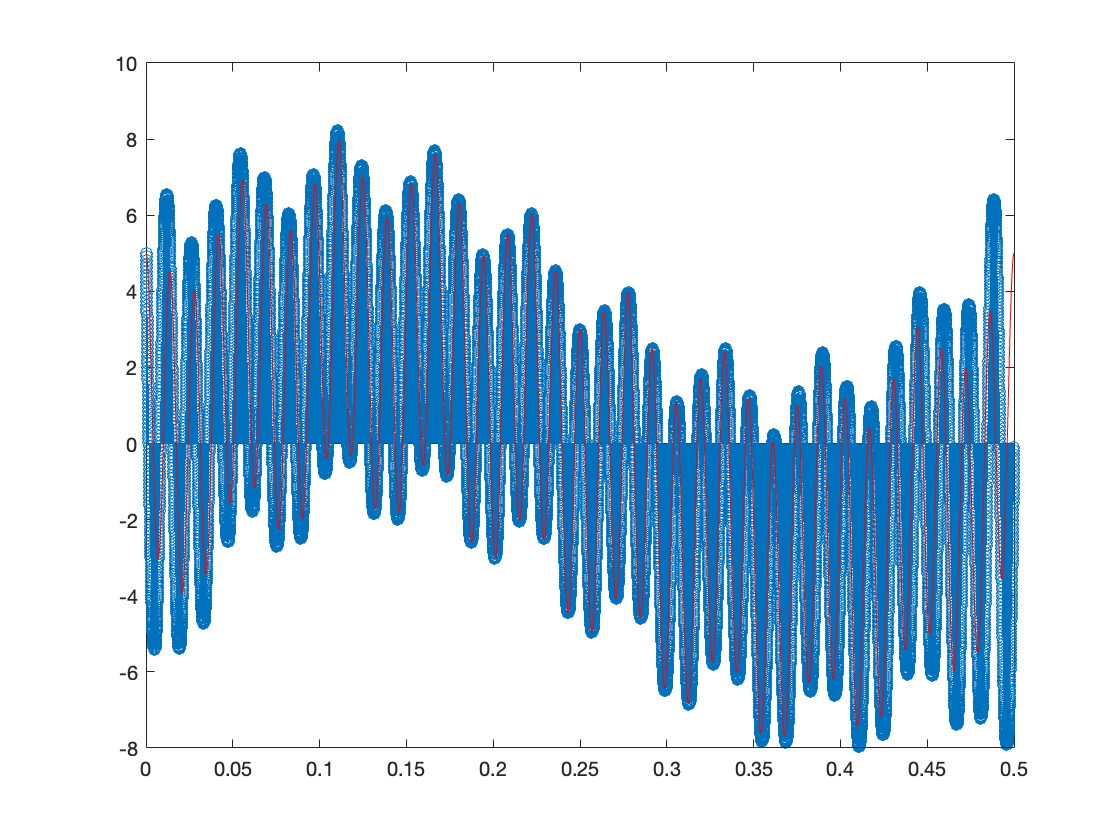


% this will "fill in" the points that were zero in frequency with values
% based on the sinc function of the surrounding points (in time)

fds = fs/SS*UU; % we get our absolute sampling rate by dividing original sampling rate (Hz) by SS (the value you downsampled at) then mult by UU (rate upsampled at)
tds = 1/fds; % this is the time interval of samples 
fdc = fds/2; %lowpass filter cutoff frequency (1/2 of our sampling rate)
xi = zeros(1,Nup);
ti = 0:tds:(Nup-1)*tds;
arg = fds*ti; %these are our sequence numbers 0 to Nup

% now we "convolve" our sampled points in frequency with the ideal lowpass filter.
% this is the equivalent of multiplying our data points in time with the
% inverse fourier transform of the ideal lowpass filter (the sinc() function)
for m = 0:Nup-1
    xi = xi+xup(m+1)*sinc((arg-2*m*fdc*tds)./UU); %divide by locations where the signal is zero
end

figure(14)
stem(arg*tds, xi)
hold on
%plot the "continuous" signal on top
plot(t,x,'-r')

% ** NOTE ** as the "continuous" signal is not actually continuous
% (discrete points in time) if you are very close to Nyquist sampling rate,
% you may see slight numerical errors between the interpolated signal and
% the "continuous" signal. 


## Interopolate the original data

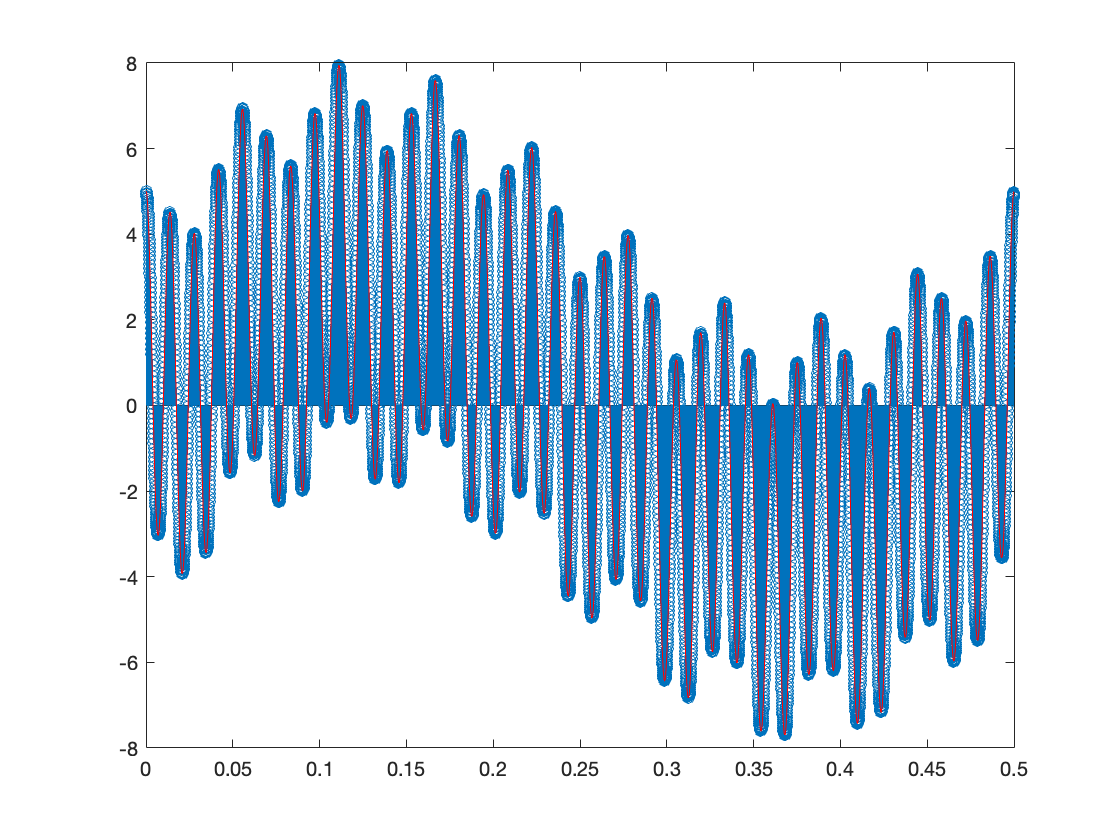


% this is a bit lame, as we just get the same data points that we sampled at (not filling
% anything in)
fc = fs/2; %/2; %lowpass filter cutoff frequency
xi = zeros(1,N);
ti = 0:ts:(N-1)*ts;
arg = fs*ti;
for m = 0:N-1
    xi = xi+xs(m+1)*sinc(arg-2*m*fc*ts);
end
figure(12)
stem(arg*ts, xi)
hold on

%note how the sinc(arg-2*n*fc*ts) is 1 at all times

% plot the "continous" function too
plot(t,x,'-r')

## Convolve with a lowpass filter of the wrong cutoff frequency

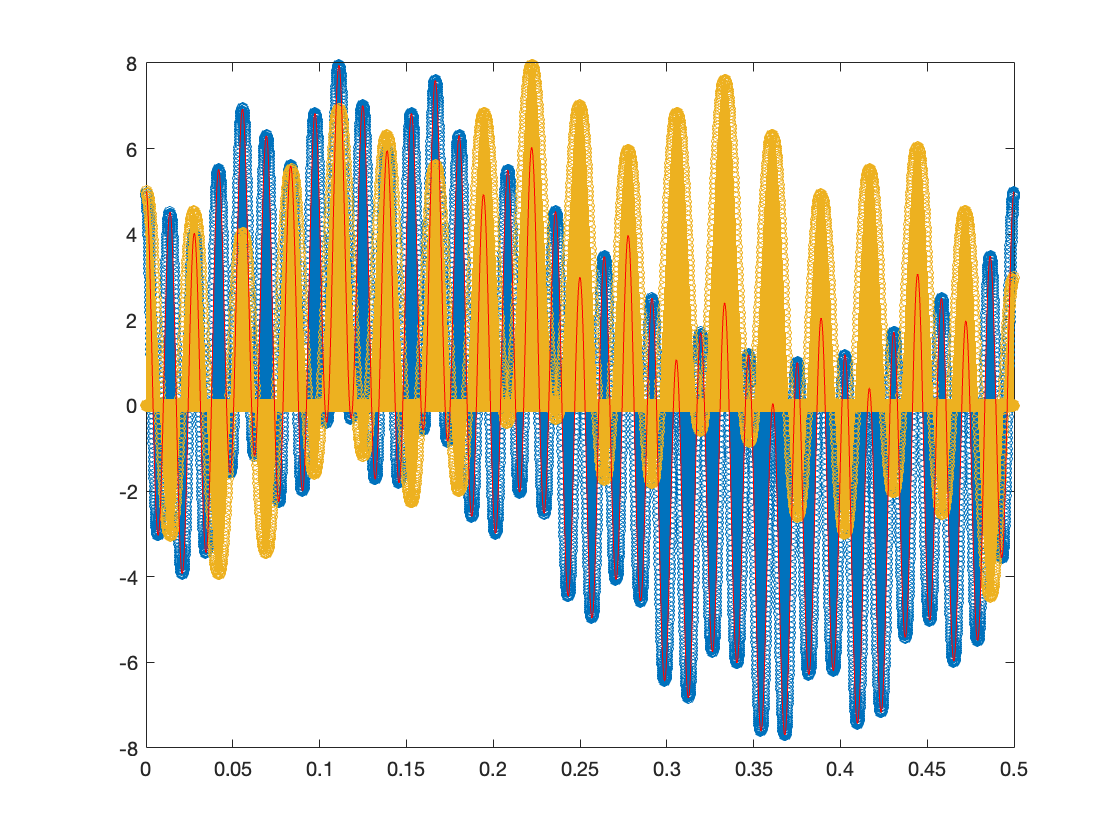


% This is for fun. You can see how the signal we get back in time now has frequencies present that should
% not be. Notice how the shape changes

fc = fs; % let all the frequencies up to our sampling rate through! (make this anything)
xi = zeros(1,N);
ti = 0:ts:(N-1)*ts;
arg = fs*ti;

for m = 0:N-1
    xi = xi+xs(m+1)*sinc((arg-2*m*fc*ts)); %sinc function centered at the m-th sample point
end

figure(12)
stem(arg*ts, xi, '-o')
hold on
%plot the continous function too
plot(t,x,'-r')